# Varying speed, varying path

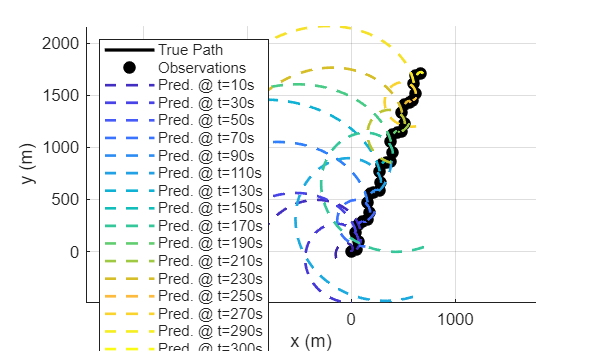

%% Sinusoidal heading + varying speed (Sparse [x,y,theta], EKF on [x y v psi omega a])
% Truth:
% v_dot = a(t)                 (time-varying acceleration)
% psi_dot = omega(t)           (sinusoidal turn-rate)
% omega(t) = Omega_amp * sin(2*pi*f_turn*t)
% a(t)     = A_acc    * sin(2*pi*f_acc *t)
% Measurements: z = [x, y, psi] + noise
% Filter: EKF with state [x; y; v; psi; omega; a], omega and a as random walks
clear; clc; close all;

%% Scenario Parameters
Tf          = 300;        % total duration [s]
dt_truth    = 0.5;        % truth integration step [s]
dt_filter   = 1;        % filter propagation step [s]
T_meas      = 10;       % measurement interval [s]
T_pred      = 60;       % prediction horizon [s]

% Initial conditions
x0_true   = 0;             % m
y0_true   = 0;             % m
v0_true   = 4.12;           % m/s
psi0_true = deg2rad(10);   % rad

% Heading modulation (sinusoidal turn-rate)
Omega_amp = deg2rad(6);    % rad/s peak turn-rate
f_turn    = 0.02;          % Hz (period ~50 s)

% Speed modulation (sinusoidal acceleration)
A_acc     = 0.3877;          % m/s^2 amplitude
f_acc     = 0.02;          % Hz

acc_fun   = @(t) A_acc   * sin(2*pi*f_acc*t);
omega_fun = @(t) Omega_amp * sin(2*pi*f_turn*t);

% Measurement noise (AIS-like)
sigma_xy  = 3;           % m
sigma_th  = deg2rad(2);  % rad

% Process noise (model errors)
sigma_v     = 0.06;          % m/s
sigma_psi   = deg2rad(0.3);  % rad
sigma_omega = deg2rad(0.12); % rad/s
sigma_a     = 0.08;          % m/s^2

rng(5); % reproducible
wrapAng = @(a) atan2(sin(a), cos(a));

%% Truth Trajectory
t_truth = 0:dt_truth:Tf;
N_truth = numel(t_truth);
% True state: [x;y;v;psi;omega;a]
X_true = zeros(6, N_truth);
X_true(:,1) = [x0_true; y0_true; v0_true; psi0_true; omega_fun(0); acc_fun(0)];

for k = 2:N_truth
    t  = t_truth(k-1);
    dt = dt_truth;

    % substep integrate (smooth curvature + accel)
    nsub = 5; dts = dt/nsub;
    x = X_true(:,k-1);
    for s = 1:nsub
        v   = x(3);
        psi = x(4);
        omg = omega_fun(t + (s-1)*dts);
        a   = acc_fun(  t + (s-1)*dts);

        % Kinematics
        x(1) = x(1) + v*cos(psi)*dts;
        x(2) = x(2) + v*sin(psi)*dts;
        x(3) = max(0, v + a*dts);
        x(4) = wrapAng(psi + omg*dts);
        x(5) = omg;   % store instantaneous omega(t)
        x(6) = a;     % store instantaneous a(t)
    end
    X_true(:,k) = x;
end

%% Measurements
t_meas = 0:T_meas:Tf;  N_meas = numel(t_meas);
z_meas = zeros(3, N_meas); % [x;y;psi]
idx_meas_truth = round(t_meas/dt_truth)+1;

for i = 1:N_meas
    kk = idx_meas_truth(i);
    x = X_true(:,kk);
    z_meas(:,i) = [ x(1) + sigma_xy*randn;
                    x(2) + sigma_xy*randn;
                    wrapAng(x(4) + sigma_th*randn) ];
end

%% EKF Model
% State x = [x; y; v; psi; omega; a]
% Propagation: NCCT+acc over dt (assume omega & a constant within each dt)
prop = @(x,dt) propagate_ncct_va(x, dt);
Fnum = @(x,dt) numJacobian(@(xx) prop(xx,dt), x);

% Measurement: z = [x; y; psi]
h    = @(x) [x(1); x(2); wrapAng(x(4))];
H    = @(x) [1 0 0 0 0 0;
             0 1 0 0 0 0;
             0 0 0 1 0 0];
R    = diag([sigma_xy^2, sigma_xy^2, sigma_th^2]);

% Discrete process noise (diagonal, tuned)
Q_from_dt = @(dt) diag([ ...
    (0.5*max(v0_true,1)*dt)^2, ...  % x diffusive proxy
    (0.5*max(v0_true,1)*dt)^2, ...
    (sigma_v*sqrt(dt))^2, ...
    (sigma_psi*sqrt(dt))^2, ...
    (sigma_omega*sqrt(dt))^2, ...
    (sigma_a*sqrt(dt))^2 ]);

%% EKF Initialisation (boot)
if N_meas < 3, error('Need at least three updates to initialise.'); end
p1 = z_meas(1:2,1); th1 = z_meas(3,1);
p2 = z_meas(1:2,2); th2 = z_meas(3,2);
p3 = z_meas(1:2,3); th3 = z_meas(3,3);

dt12 = t_meas(2) - t_meas(1);
dt23 = t_meas(3) - t_meas(2);

% Coarse seeds
v12     = norm(p2 - p1)/max(dt12,1e-6);
v23     = norm(p3 - p2)/max(dt23,1e-6);
a_init  = (v23 - v12)/max(dt23,1e-6);
psi_init   = th2;
omega_init = wrapAng(th3 - th2)/max(dt23,1e-6);

xhat = [p2(1); p2(2); max(v12,0.1); psi_init; omega_init; a_init];
Phat = diag([ (4*sigma_xy)^2, (4*sigma_xy)^2, ...
              (max(v12,0.5))^2, deg2rad(10)^2, (deg2rad(2)/max(dt23,1))^2, 0.25^2 ]);

%% Run EKF & Predict
t_filter = 0:dt_filter:Tf; N_filt = numel(t_filter);
X_filt   = nan(6, N_filt);

predictions = cell(N_meas,1);
pred_truth  = cell(N_meas,1);
% Stats columns:
% [t_update, RMSE_pos, MAE_pos, v_est, v_err, psi_est, psi_err_deg, omega_est, omega_err_deg_s, a_est, a_err]
pred_stats  = [];

meas_ptr = 1;
for k = 1:N_filt
    t_now = t_filter(k);

    % Predict
    Fk  = Fnum(xhat, dt_filter);
    Qk  = Q_from_dt(dt_filter);
    xhat = prop(xhat, dt_filter);
    Phat = Fk*Phat*Fk' + Qk;
    X_filt(:,k) = xhat;

    % Update on measurement times
    if meas_ptr <= N_meas && abs(t_now - t_meas(meas_ptr)) < 1e-9
        z = z_meas(:,meas_ptr);
        zhat = h(xhat);

        innov = z - zhat; innov(3) = wrapAng(innov(3));
        Hk = H(xhat); S = Hk*Phat*Hk' + R; K = Phat*Hk'/S;

        xhat = xhat + K*innov;
        Phat = (eye(6) - K*Hk)*Phat;

        % Roll out a T_pred prediction using NCCT+acc model
        Np = round(T_pred/dt_filter);
        future = zeros(6, Np+1); future(:,1) = xhat;
        xpr = xhat; Ppr = Phat;
        for j = 2:Np+1
            Fp = Fnum(xpr, dt_filter);
            Qp = Q_from_dt(dt_filter);
            xpr = prop(xpr, dt_filter);
            Ppr = Fp*Ppr*Fp' + Qp;
            future(:,j) = xpr;
        end

        % Truth over the same horizon
        t0 = t_now; tfh = min(t_now + T_pred, Tf);
        idx0 = round(t0/dt_truth)+1;
        idxf = min(round(tfh/dt_truth)+1, N_truth);
        truth_seg = X_true(:, idx0:idxf);

        predictions{meas_ptr} = struct('t0',t0,'dt',dt_filter,'states',future);
        pred_truth{meas_ptr}  = struct('states',truth_seg);

        % Metrics (position over horizon)
        np = min(size(future,2), size(truth_seg,2));
        pred_xy = future(1:2,1:np);
        true_xy = truth_seg(1:2,1:np);
        pos_err = vecnorm(pred_xy - true_xy, 2, 1);
        rmse_pos = sqrt(mean(pos_err.^2));
        mae_pos  = mean(abs(pos_err));

        v_est_k    = xhat(3);
        psi_est_k  = xhat(4);
        omg_est_k  = xhat(5);
        a_est_k    = xhat(6);

        v_true_k   = X_true(3, idx0);
        psi_true_k = X_true(4, idx0);
        omg_true_k = X_true(5, idx0);
        a_true_k   = X_true(6, idx0);

        v_err   = v_est_k - v_true_k;
        psi_err = rad2deg(wrapAng(psi_est_k - psi_true_k));
        omega_err = rad2deg(omg_est_k - omg_true_k); % deg/s
        a_err   = a_est_k - a_true_k;

        pred_stats = [pred_stats; t_now, rmse_pos, mae_pos, ...
                      v_est_k, v_err, psi_est_k, psi_err, omg_est_k, omega_err, a_est_k, a_err]; %#ok<AGROW>

        meas_ptr = meas_ptr + 1;
    end
end

%% Plots
% Plot 1
figure('Color','w','Position',[60 60 1200 700]);
hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

% Truth path and observations
plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2, 'DisplayName', 'True Path');
plot(z_meas(1,:), z_meas(2,:), 'ko', 'MarkerSize', 7, ...
     'MarkerFaceColor','k', 'DisplayName', 'Observations');

% Coloured horizons (label every 2nd, and always the last, to avoid legend spam)
n_updates = numel(predictions);
draw_idx  = 1:n_updates;                   % draw all
colors    = parula(numel(draw_idx));       % (parula/turbo/lines)

for ii = 1:numel(draw_idx)
    i = draw_idx(ii);
    S = predictions{i};
    if isempty(S), continue; end
    xy = S.states(1:2,:);
    if mod(i,2)==0 || i==draw_idx(end)
        lbl = sprintf('Pred. @ t=%.0fs', round(t_meas(i)));
        vis = 'on';
    else
        lbl = '';
        vis = 'off';
    end
    plot(xy(1,:), xy(2,:), '--', 'Color', colors(ii,:), ...
         'LineWidth', 1.6, 'DisplayName', lbl, 'HandleVisibility', vis);
end

legend('Location','northwest');

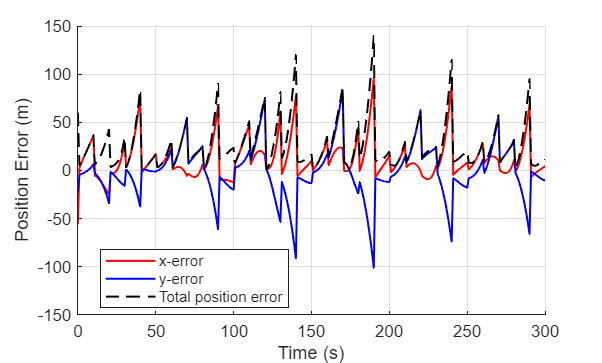


% Plot 2
%% Compute and Plot Position Error 
% Interpolate EKF filtered estimates onto truth time grid for fair comparison
valid_idx = find(all(~isnan(X_filt(1:2,:)),1));
t_valid   = t_filter(valid_idx);
x_filt_i  = interp1(t_valid, X_filt(1,valid_idx), t_truth, 'linear', 'extrap');
y_filt_i  = interp1(t_valid, X_filt(2,valid_idx), t_truth, 'linear', 'extrap');

% Compute position error components
x_err = X_true(1,:) - x_filt_i;
y_err = X_true(2,:) - y_filt_i;
pos_err_total = sqrt(x_err.^2 + y_err.^2);

% Plot errors
figure('Color','w'); hold on; grid on;
plot(t_truth, x_err, 'r', 'LineWidth', 1.2);
plot(t_truth, y_err, 'b', 'LineWidth', 1.2);
plot(t_truth, pos_err_total, 'k--', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Position Error (m)');
legend({'x-error','y-error','Total position error'}, 'Location','best');

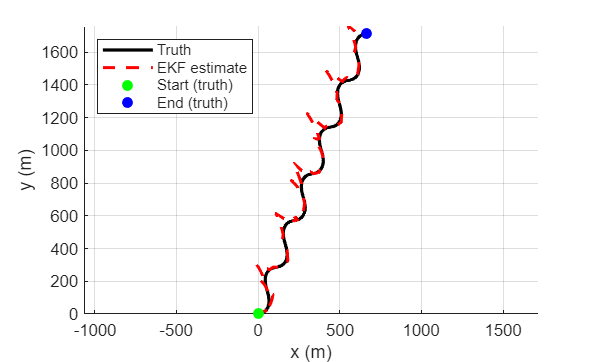


% Plot 3
% Trajectory comparison (x–y): Truth vs EKF estimates
figure(5); clf; hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

% True trajectory (from X_true built earlier)
plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2, 'DisplayName','Truth');

% EKF trajectory (from X_filt built during filtering)
% Keep only valid (non-NaN) samples
valid_idx = find(all(~isnan(X_filt(1:2,:)),1));
x_est = X_filt(1, valid_idx);
y_est = X_filt(2, valid_idx);
plot(x_est, y_est, 'r--', 'LineWidth', 1.8, 'DisplayName','EKF estimate');

% Start/end markers
plot(X_true(1,1),      X_true(2,1),      'go', 'MarkerFaceColor','g', 'DisplayName','Start (truth)');
plot(X_true(1,end),    X_true(2,end),    'bo', 'MarkerFaceColor','b', 'DisplayName','End (truth)');

legend('Location','northwest');


%% Console Stats
if ~isempty(pred_stats)
    mean_rmse   = mean(pred_stats(:,2));
    median_rmse = median(pred_stats(:,2));
    mean_mae    = mean(pred_stats(:,3));
    last_row    = pred_stats(end,:);

    fprintf('--- Prediction Summary (Sin heading + Var speed, H=%.0f s, updates %.0f s) ---\n', T_pred, T_meas);
    fprintf('Omega amplitude   : %+6.3f deg/s | f_turn = %.3f Hz\n', rad2deg(Omega_amp), f_turn);
    fprintf('Accel amplitude   : %+6.3f m/s^2 | f_acc  = %.3f Hz\n', A_acc, f_acc);
    fprintf('Avg RMSE (pos)    : %.3f m | Median: %.3f m | Avg MAE: %.3f m\n', mean_rmse, median_rmse, mean_mae);

    fprintf('\nLast update at t=%.0f s:\n', last_row(1));
    fprintf('  Pred. speed     : %.3f m/s (err = %+6.3f m/s)\n', last_row(4), last_row(5));
    fprintf('  Pred. heading   : %+6.2f deg (err = %+6.2f deg)\n', rad2deg(last_row(6)), last_row(7));
    fprintf('  Pred. turn-rate : %+6.3f deg/s (err = %+6.3f deg/s)\n', rad2deg(last_row(8)), last_row(9));
    fprintf('  Pred. accel     : %+6.3f m/s^2 (err = %+6.3f m/s^2)\n', last_row(10), last_row(11));
    fprintf('  Horizon RMSE    : %.3f m\n', last_row(2));
else
    fprintf('No prediction stats computed (insufficient updates?).\n');
end

--- Prediction Summary (Sin heading + Var speed, H=60 s, updates 10 s) ---


Omega amplitude   : +6.000 deg/s | f_turn = 0.020 Hz


Accel amplitude   : +0.388 m/s^2 | f_acc  = 0.020 Hz


Avg RMSE (pos)    : 315.946 m | Median: 127.006 m | Avg MAE: 255.322 m



Last update at t=300 s:


  Pred. speed     : 3.110 m/s (err = -1.010 m/s)


  Pred. heading   : +10.99 deg (err =  +0.99 deg)


  Pred. turn-rate : -4.469 deg/s (err = -4.394 deg/s)


  Pred. accel     : -0.235 m/s^2 (err = -0.230 m/s^2)


  Horizon RMSE    : 3.823 m



%% Helpers
function xnext = propagate_ncct_va(x, dt)
    % Nearly-constant turn-rate + acceleration within dt
    % x = [x; y; v; psi; omega; a]
    xn = x;
    nsub = 3; dts = dt/nsub;   % small substeps for stability
    for s = 1:nsub
        v   = xn(3); psi = xn(4); omg = xn(5); a = xn(6);
        xn(1) = xn(1) + v*cos(psi)*dts;
        xn(2) = xn(2) + v*sin(psi)*dts;
        xn(3) = max(0, v + a*dts);
        xn(4) = atan2(sin(psi + omg*dts), cos(psi + omg*dts));
        % omega and a are random walks: held constant in prop; Q adds diffusion
    end
    xnext = xn;
end

function F = numJacobian(f, x)
    n = numel(x); fx = f(x); m = numel(fx);
    F = zeros(m,n); eps = 1e-6;
    for i = 1:n
        dx = zeros(n,1); dx(i) = eps;
        F(:,i) = (f(x+dx) - fx)/eps;
    end
end